# Práctica 3. Señal no estacionaria

#### Tarea propuesta: 

Identificación de una secuencia de teclas pulsadas. 

**a)** El audio “marcación.wav” contiene el sonido resultante de pulsar una secuencia de teclas. Carga la señal contenida en “marcación.wav”, oye la señal y represéntala en el dominio temporal.

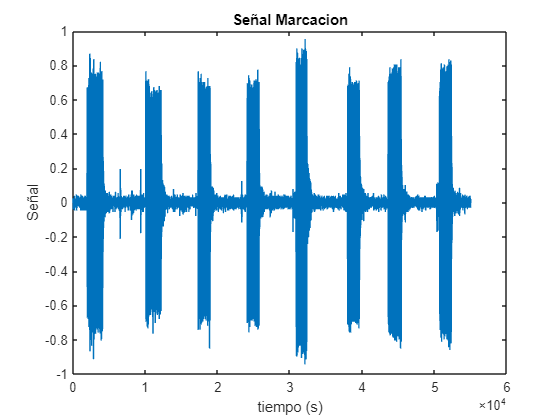

clear all
close all

[x,fs] = audioread('marcacion.wav');
n=length(x);
t=0:1:n-1;
figure()
plot(t,x)
ylabel('Señal')
xlabel('tiempo (s)')
title('Señal Marcacion');

sound(x,fs);

**b)** Representa la señal completa en el dominio de la frecuencia.

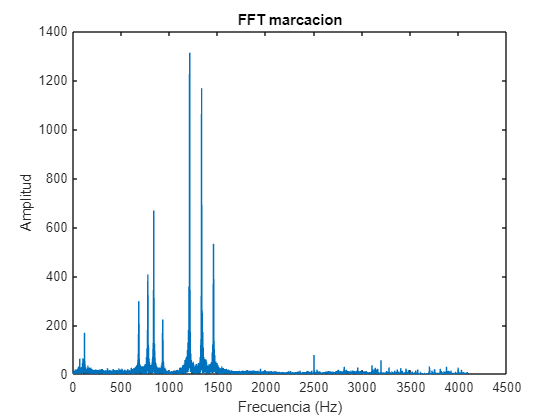

ft = abs(fft(x));
freq = t*fs/n;
ft = ft(freq<fs/2);
freq = freq(freq<fs/2);
figure()
plot(freq,ft);
ylabel('Amplitud')
xlabel('Frecuencia (Hz)')
title('FFT marcacion');   

**c)** Divide la señal en los segmentos asociados a cada pulsación de tecla, y analiza los segmentos en el dominio de la frecuencia.

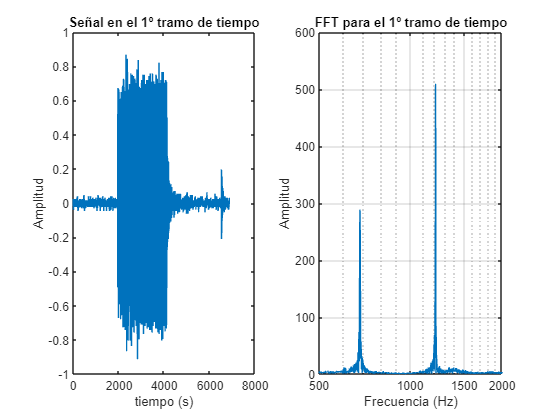

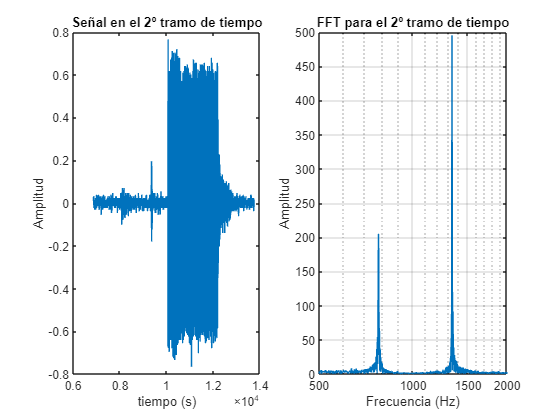

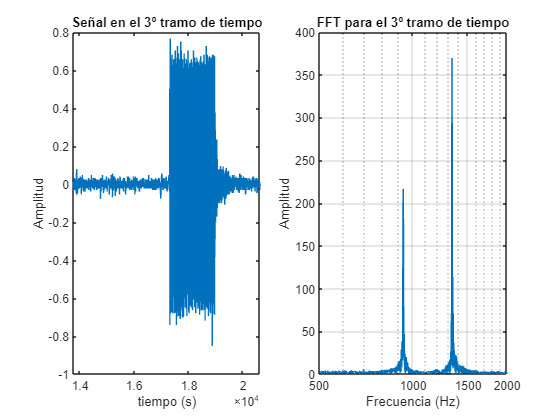

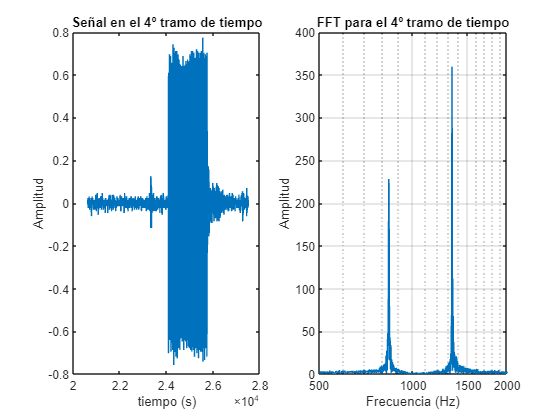

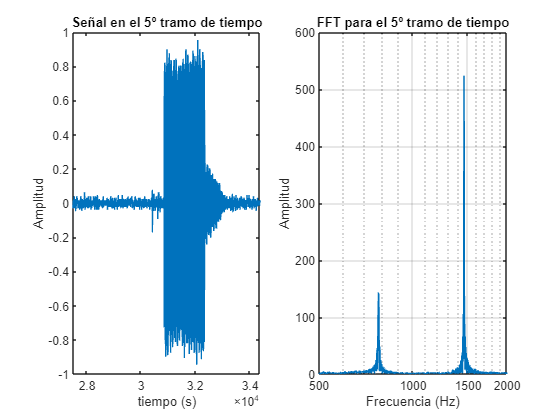

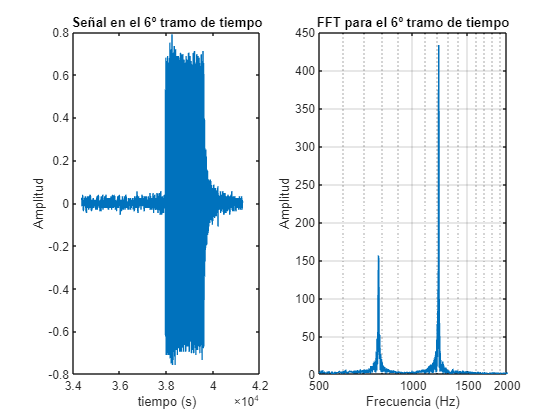

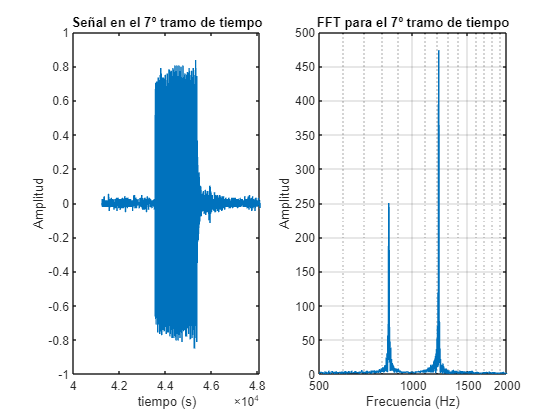

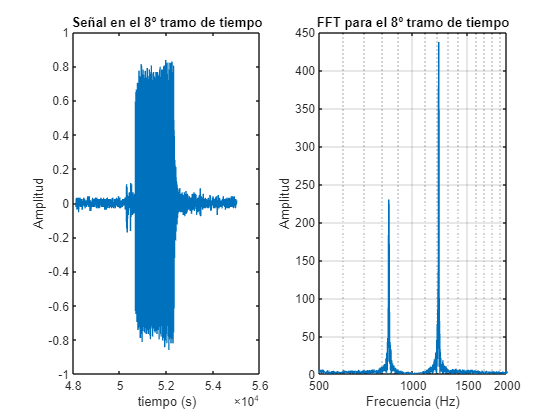

notas = zeros(n/8,8);

for i = 1:8
    figure()
    % Calcular el rango para cada parte del array
    rango_inicio = 1 + (i - 1) * (n / 8);
    rango_fin = i * (n / 8);
    freq = (0:1:n/8-1)*fs/n*8;
    % Asignar la parte correspondiente a la fila i de la matriz
    notas(:,i) = x(rango_inicio:rango_fin);
    subplot(1,2,1)
    plot(rango_inicio:rango_fin,notas(:,i))
    ylabel('Amplitud')
    xlabel('tiempo (s)')
    titulo = sprintf('Señal en el %dº tramo de tiempo',i);
    title(titulo)
    subplot(1,2,2)
    semilogx(freq,abs(fft(notas(:,i))));
    grid;
    xlim([500,2000])
    ylabel('Amplitud')
    xlabel('Frecuencia (Hz)')
    titulo = sprintf('FFT para el %dº tramo de tiempo',i);
    title(titulo)
end

**d)** Representa el espectrograma de la señal completa.

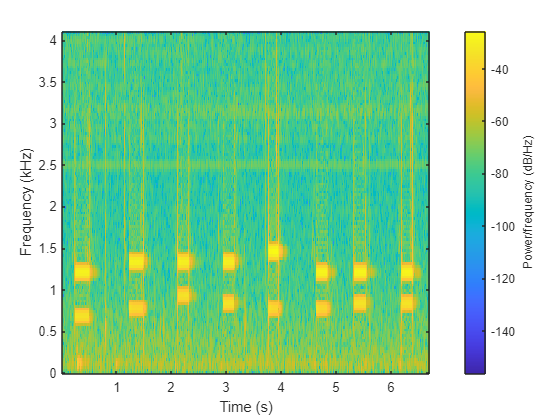

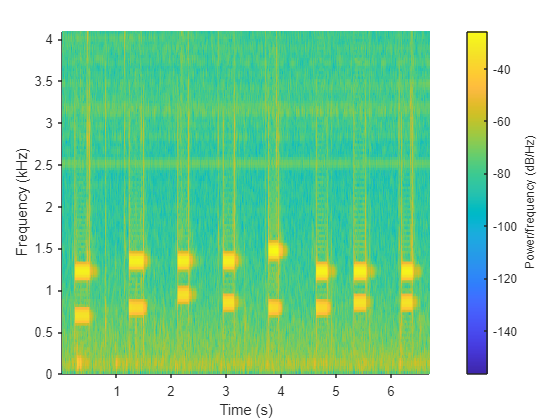

figure()
spectrogram(x,128,120,[],fs)
view(90,-90)